# Get Started with Problem-Based Optimize Live Editor Task

This example script helps you to use the problem-based **Optimize** Live Editor task for optimization or equation solving. Modify the script for your own problem.

The script solves a nonlinear optimization problem with nonlinear constraints:

Minimize ${\rm rosenbrock}(x,y,a)=\log\left (1+a(y - x^2)^2 + (1-x)^2\right)$ subject to the constraint $x^2+y^2\le 1$, where $a=100$ and the initial point $x0$ has $x=-2,\ y=2$. Also, impose the bounds $-3\le x\le 3$, $-2\le y\le 9$.

The code for the objective function appears at the end of this script.

## Include Parameters or Data

Typically, you have data or values to pass to the solver. Place those values in the input section (where you see `x0x` and `x0y`) and run the section by choosing **Section > Run Section** or pressing `Control+Enter`.

Set the initial point components `x0x` and `x0y` and scale `a` for the optimization.

x0x = -2;
x0y = 2;
a = 100;

**Place these values and any other problem data into the workspace** by running this section before proceeding.

## Optimize Live Editor Task

Usually, you place the Optimize Live Editor task into the script by selecting **Task > Optimize** in the **Live Editor** tab, or by selecting **Task > Optimize** in the **Insert** tab. Then you are presented with the following choice (this is only a picture, not the real task):

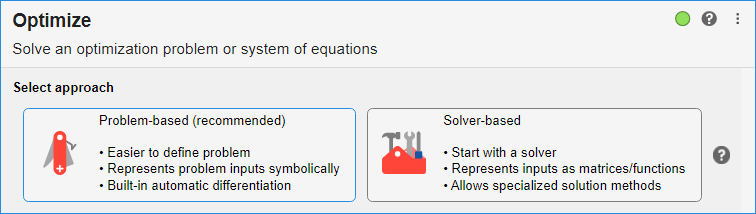

To get the problem-based task, click **Problem-based (recommended)**.

The following problem-based task has the variables, objective, and constraint filled in. Modify it for your problem, or run it as is to see how the task works. To modify the problem, click the **Define problem** button at the bottom of the task. To run the task, click the **Solve problem** button at the bottom of the task.

% Create optimization variables
x2 = optimvar("x","LowerBound",-3,"UpperBound",3);
y2 = optimvar("y","LowerBound",-2,"UpperBound",9);

% Set initial starting point for the solver
initialPoint.x = x0x;
initialPoint.y = x0y;

% Create problem
problem = optimproblem;

% Define problem objective
problem.Objective = fcn2optimexpr(@rosenbrock,x2,y2,a);

% Define problem constraints
problem.Constraints = x2^2 + y2^2 <= 1;

% Display problem information
show(problem);


  OptimizationProblem : 

	Solve for:
       x, y

	minimize :
       log(((1 + (100 .* (y - x.^2).^2)) + (1 - x).^2))


	subject to :
       (x.^2 + y.^2) <= 1

	variable bounds:
       -3 <= x <= 3

       -2 <= y <= 9




% Solve problem
[solution,objectiveValue,reasonSolverStopped] = solve(problem,initialPoint,...
    "Solver","ga");

Solving problem using ga.
Optimization finished: average change in the fitness value less than options.FunctionTolerance and constraint violation is less than options.ConstraintTolerance.



% Display results
solution

solution = struct with fields:
    x: 0.7867
    y: 0.6182


reasonSolverStopped

reasonSolverStopped =     SolverConvergedSuccessfully


objectiveValue

objectiveValue = 0.0445


% Clear variables
clearvars x2 y2 initialPoint reasonSolverStopped objectiveValue

## Interpret Results

The task calls `solve`, which calls `fmincon` to solve the problem. The top of the task shows that the solution is returned in the `solution` structure. The reported solution, `x = 0.7864` and `y = 0.6177`, satisfies the constraint $x^2+y^2\le 1$, as you can see in the following calculation.

solution.x^2 + solution.y^2                                     

ans = 1.0010

The solver reports exit condition `OptimalSolution` when it stops. To interpret this condition, look at the `exitflag` [output of `solve`](docid:optim_ug.mw_cedf587e-dc58-476c-a675-a44b82bff7c5) for the `fmincon` solver. The description states "First-order optimality measure is less than options.OptimalityTolerance, and maximum constraint violation is less than options.ConstraintTolerance." In other words, the solution is a feasible local minimum.

The objective function value at the solution is 0.0457. This is the smallest objective function value among feasible points.

## Helper Functions

This code creates the `rosenbrock` helper function.

function objective = rosenbrock(x,y,a)
% This function should return a scalar representing an optimization objective.

% Example: Concession stand profit
% revenue = 3*soda + 5*popcorn + 2*candy;
% cost = 1*soda + 2*popcorn + 0.75*candy;
% objective = revenue - cost; % profit

% Edit the lines below with your calculations.
objective = log(1 + a*(y - x^2)^2 + (1 - x)^2);
end

*Copyright 2021-2022 The MathWorks, Inc.*